# Synchronized Event Mining 1 pair (contamination + transformation)

#### Data description 

Cabin - Bin calcium signal every 1 second;

ca_cl - calcium data after contamination clearance 

K - length of event; M - number of neurons; 

time - (cell array) time where each event starts, each cell stores events for one m,k combination; 

cells - (cell array) cell index in each event, each cell stores events for one m,k combination; 

pvl - p value for each m,k combination.

#### Remove contamination and Transform data 

p=3; % pair index (6 pair tube assay dataset)
load('remov.mat');ca_cl=cell(1,2);
for m =1:2 % mouse index
    ca=zscore(E{p}{m}.dFFCalciumTraces);
    ca(:,remov{p,m})=[]; % remove contamination
    % 1-second time bins
    [L,nc]=size(ca); s=floor(L/30); cabin=zeros(s,nc);
    for t=1:s
        cabin(t,:)=sum(ca(30*(t-1)+1:30*t,:),1);
    end
    % set maximun at the 95% percentile
    acc=sort(cabin,1,'ascend');
    thre=acc(ceil(0.95*size(cabin,1)),:);
    for c=1:nc
        cabin(cabin(:,c)>=thre(c),c)=thre(c);
    end
    % normalize to 0-1
    cabin=(cabin-min(cabin))./(max(cabin)-min(cabin));
    ca_cl{p,m}=cabin'; % cell x length
end

####  Define and Identify Events 

Analyze events with 0.4, 0.5, 0.6 threshold. 

close all
thre=[0.4,0.5,0.6]; % thresholds for event identification 
em=cell(2,length(thre));
R=1; % first round 
for th=1:length(thre)
    eve=cell(1,2);randeve=cell(1,2);
    parfor m=1:2
        [eve{p,m}]=eventmining(ca_cl{p,m},120,thre(th));
        % 100 random shuffles
        [randeve{p,m}]=randevent(ca_cl{p,m},100,120,thre(th));
    end
    em{R,th}.eve=eve;em{R,th}.randeve=randeve;
end

#### Plot event frequency and event/random ratio 

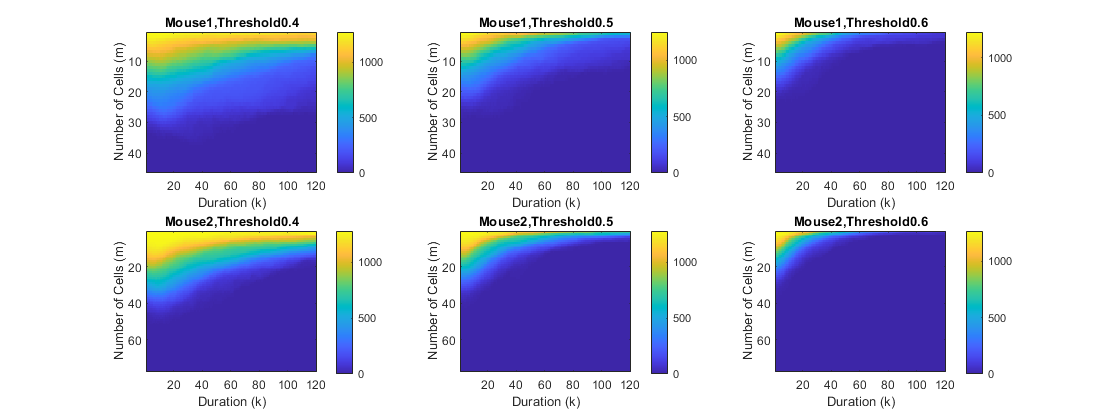

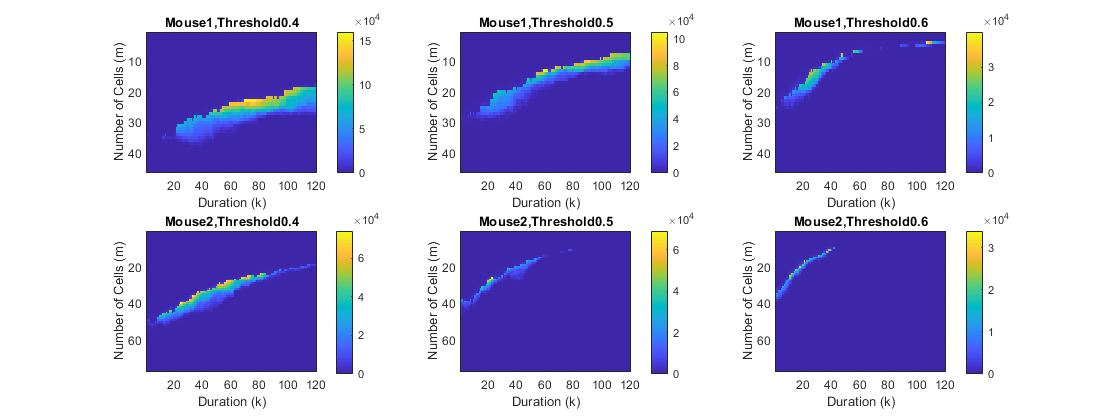

close all
f1=figure(1);f1.Position(3)=2*f1.Position(3);
f2=figure(2);f2.Position(3)=2*f2.Position(3);
for th=1:length(thre)
    eve=em{R,th}.eve;randeve=em{R,th}.randeve;
    for m=1:2
        figure(1)
        subplot(2,3,3*(m-1)+th)
        mc=ceil(size(eve{p,m},1)/2);% plot 1/2 of total cell number
        imagesc(eve{p,m}(1:mc,:));title(sprintf('Mouse%d,Threshold%.1f',m,thre(th)))
        xlabel('Duration (k)');ylabel('Number of Cells (m)');colorbar
        figure(2)
        subplot(2,3,3*(m-1)+th)
        randeve{p,m}(randeve{p,m}==0)=0.001;% if no event in random trace set as 0.001
        rat=eve{p,m}(1:mc,:)./squeeze(mean(randeve{p,m}(:,1:mc,:),1)); % event - random ratio
        imagesc(rat,'AlphaData',~isnan(rat));set(gca,'color',[1 1 1]);xlabel('Duration (k)');ylabel('Number of Cells (m)')
        title(sprintf('Mouse%d,Threshold%.1f',m,thre(th)));colorbar;
    end
end

#### Find Most Significant Combinations 

R=1;
for th=1:length(thre)
    eve=em{R,th}.eve;randeve=em{R,th}.randeve;
    alp=0.01; % the percentage of mk conbinations to include
    M=cell(1,2);K=cell(1,2);cells=cell(1,2);time=cell(1,2);pvl=cell(1,2);
    for m=1:2
        nc=size(eve{p,m},1);nr=floor(120*nc*alp); % number of combination to take
        randeve{p,m}(randeve{p,m}==0)=0.001; % if no event in random trace set as 0.001
        rat=eve{p,m}./squeeze(mean(randeve{p,m},1)); % event/random ratio
        [~,ind]=maxk(rat(:), nr);
        [M{p,m},K{p,m}]=ind2sub([nc,120],ind); % take highet r combi
        cells{p,m}=cell(1,nr);time{p,m}=cell(1,nr);pvl{p,m}=[];
        for k = 1:nr % combinations
            % check p value
            pvl{p,m}(k)=sum(randeve{p,m}(:,M{p,m}(k),K{p,m}(k))>eve{p,m}(M{p,m}(k),K{p,m}(k)))/100;
            if pvl{p,m}(k)>0.05 % skip combi if not significant
                sprintf('combination%d,p=%.2f',k,pvl{p,m}(k))
                continue
            end
            [cells{p,m}{k},time{p,m}{k}]=mkeve(M{p,m}(k),K{p,m}(k),ca_cl{p,m},thre(th)); % find event for this combi
        end
    end
    em{R,th}.K=K;em{R,th}.M=M;em{R,th}.time=time;em{R,th}.cells=cells;em{R,th}.pvl=pvl;
end

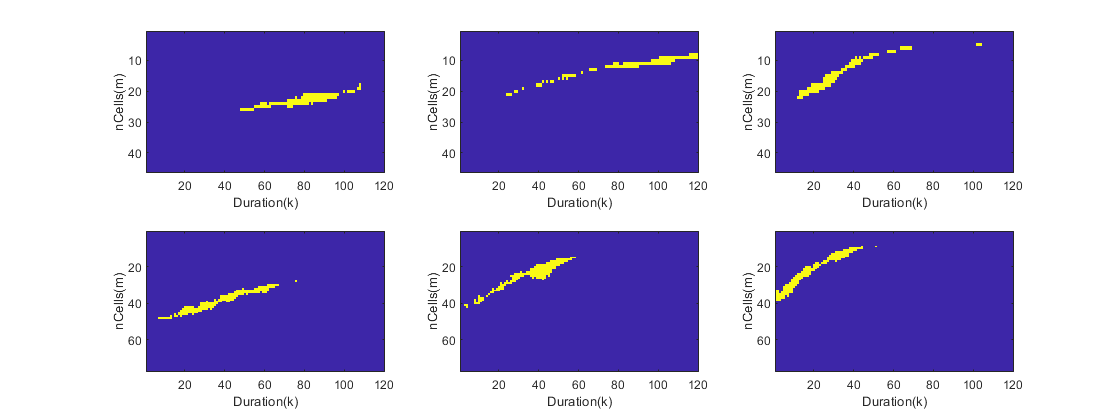

% plot selected m,k combinations
close all
f1=figure(1);f1.Position(3)=2*f1.Position(3);
for th=1:length(thre)
    M=em{R,th}.M;K=em{R,th}.K;
    for m=1:2
        sel=zeros(size(eve{p,m},1),120);
        for i=1:length(M{p,m})
        sel(M{p,m}(i),K{p,m}(i))=1;
        end
        figure(1)
        subplot(2,3,3*(m-1)+th)
        imagesc(sel(1:ceil(size(eve{p,m},1)/2),:));xlabel('Duration(k)');ylabel('nCells(m)');
    end
end

#### Plot Events on Time Axis 

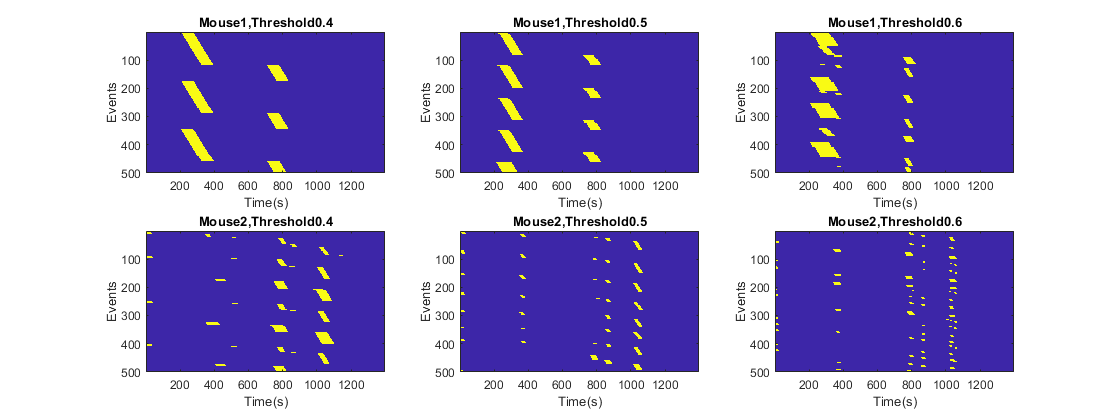

close all
f1=figure(1);f1.Position(3)=2*f1.Position(3);
for th=1:length(thre)
    time=em{R,th}.time;K=em{R,th}.K;
    eserie=cell(1,2);
    for m = 1:2
        s=size(ca_cl{p,m},2); 
        eserie{m}=[];% collection of events 
        for r=1:length(time{p,m})% number of combi
            for e=1:length(time{p,m}{r}) % number of events for each combi
                ful=zeros(1,s);
                ful(time{p,m}{r}(e):time{p,m}{r}(e)+K{p,m}(r))=1;
                eserie{m}=[eserie{m};ful];
            end
            if size(eserie{m},1)>500 % plot first 500 events from top combinations
                break
            end
        end
        figure(1)
        subplot(2,3,3*(m-1)+th)
        l=min(size(eserie{m},1),500); 
        es=eserie{m}(1:l,:);
        imagesc(es,'AlphaData',~isnan(es));xlabel('Time(s)');ylabel('Events');
        title(sprintf('Mouse%d,Threshold%.1f',m,thre(th)));
    end
end

#### Plot number of Events at each time point 

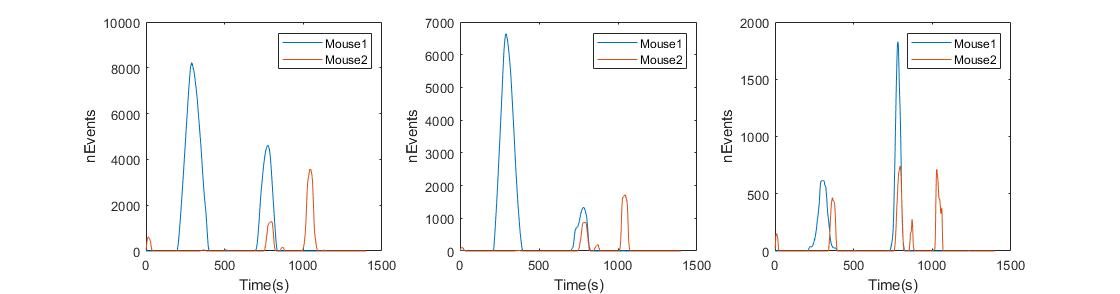

close all
f1=figure(1);f1.Position(3)=2*f1.Position(3);f1.Position(4)=0.7*f1.Position(4);
for th=1:length(thre)
    time=em{R,th}.time;K=em{R,th}.K;
    for m = 1:2
        s=size(ca_cl{p,m},2); 
        ne{p,m}=zeros(1,s);
        for r=1:length(time{p,m})% combi index
            for e=1:length(time{p,m}{r}) % events for this combi
                ne{p,m}(time{p,m}{r}(e):time{p,m}{r}(e)+K{p,m}(r))=ne{p,m}(time{p,m}{r}(e):time{p,m}{r}(e)+K{p,m}(r))+1;
                % for each event add one 
            end
        end
    end
    d=[ne{p,1};ne{p,2}];
    subplot(1,3,th)
    plot(d');xlabel('Time(s)');ylabel('nEvents');legend({'Mouse1','Mouse2'})
    em{R,th}.ne=ne;
end

#### Plot Reordered Signal according to Events 

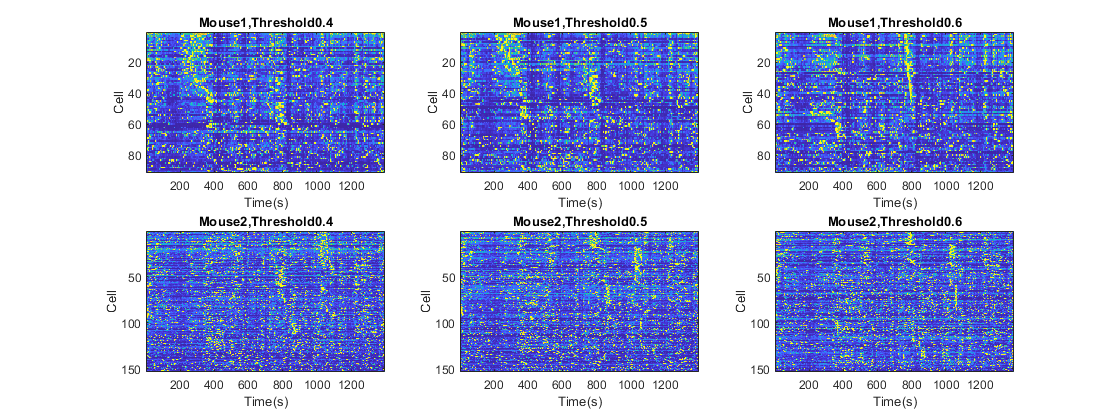

close all
f1=figure(1);f1.Position(3)=2*f1.Position(3);
for th=1:length(thre)
    eve=em{R,th}.eve;cells=em{R,th}.cells;
    c=cell(1,2);
    for m=1:2
        nc=size(eve{p,m},1);c{m}=[1:nc]';
        for i=1:length(cells{p,m})
            c{m}=[cells{p,m}{i}(:);c{m}]; % connect cells contributing to events
        end
        c{m}=unique(c{m},'stable');c{m}=c{m}(c{m}~=0); % remove duplicating cell index 
        figure(1)
        subplot(2,3,3*(m-1)+th)
        d=ca_cl{p,m}(c{m},:);  % reorder according to event cells 
        imagesc(d,'AlphaData',~isnan(d));xlabel('Time(s)');ylabel('Cell');
        title(sprintf('Mouse%d,Threshold%.1f',m,thre(th)));
    end
end

#### Second round detection 

Remove time with events and detect event again. 

R=2;
% remove event times from first round
for th=1:length(thre)
    ne=em{R-1,th}.ne;
    for m=1:2
        no_eve{p,m} = rem_eve_time(ne{p,m},5);% merge events with less than 5s interval
        ca_2=ca_cl{p,m}(:,no_eve{p,m}); % remove time of the events
        [eve{p,m}]=eventmining(ca_2,120,thre(th)); % re-run the events
        % 100 random shuffles
        [randeve{p,m}]=randevent(ca_2,100,120,thre(th));
    end
    em{R,th}.eve=eve;em{R,th}.randeve=randeve;em{R,th}.timefilter=no_eve;
end

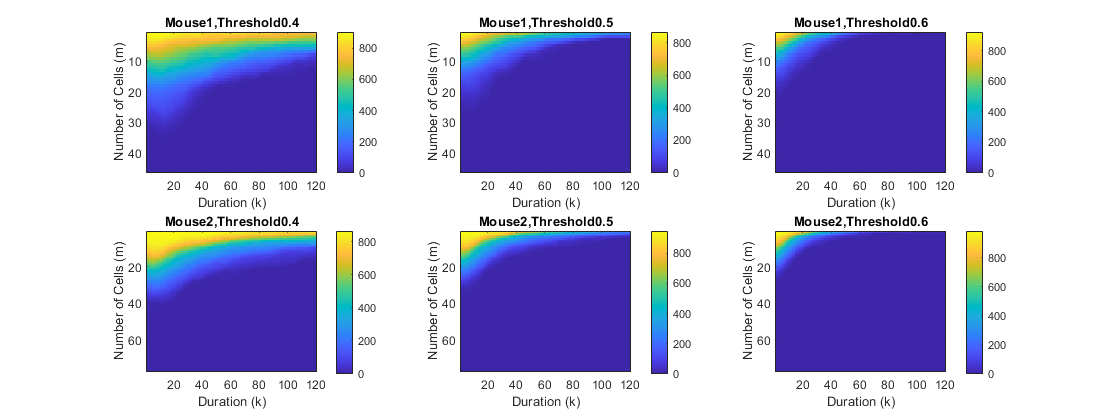

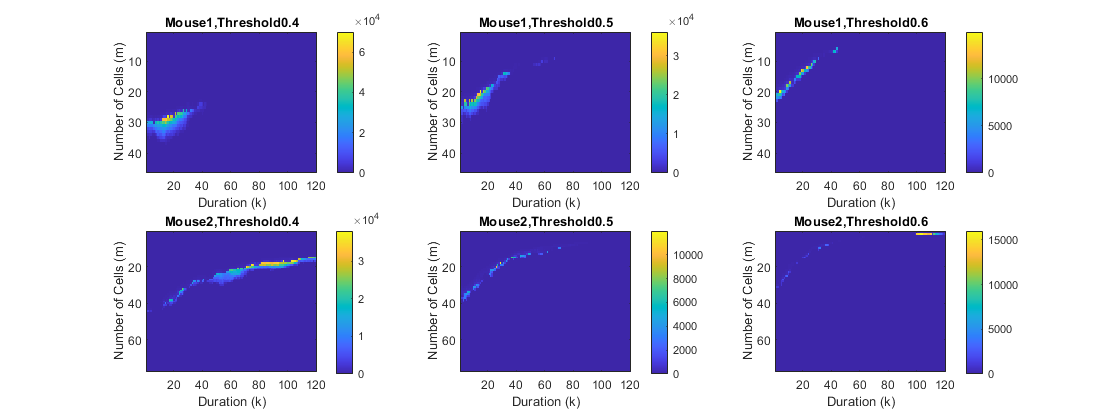

% plot event frequency and ratio 
close all 
f1=figure(1);f1.Position(3)=2*f1.Position(3);
f2=figure(2);f2.Position(3)=2*f2.Position(3);
for th=1:length(thre)
    eve=em{R,th}.eve;randeve=em{R,th}.randeve;
    for m=1:2
        figure(1)
        subplot(2,3,3*(m-1)+th)
        mc=ceil(size(eve{p,m},1)/2);% plot 1/2 of total cell number
        imagesc(eve{p,m}(1:mc,:));title(sprintf('Mouse%d,Threshold%.1f',m,thre(th)))
        xlabel('Duration (k)');ylabel('Number of Cells (m)');colorbar
        figure(2)
        subplot(2,3,3*(m-1)+th)
        randeve{p,m}(randeve{p,m}==0)=0.001;% if no event in random trace set as 0.001
        rat=eve{p,m}(1:mc,:)./squeeze(mean(randeve{p,m}(:,1:mc,:),1)); % event - random ratio
        imagesc(rat,'AlphaData',~isnan(rat));set(gca,'color',[1 1 1]);xlabel('Duration (k)');ylabel('Number of Cells (m)')
        title(sprintf('Mouse%d,Threshold%.1f',m,thre(th)));colorbar;
    end
end

#### Find events for significant combinations 

for th=1:length(thre)
    eve=em{R,th}.eve;randeve=em{R,th}.randeve;timeft=em{R,th}.timefilter;
    alp=0.005; % the percentage of mk conbinations to include
    M=cell(1,2);K=cell(1,2);cells=cell(1,2);time=cell(1,2);pvl=cell(1,2);
    for m=1:2
        nc=size(eve{p,m},1);nr=floor(120*nc*alp); % number of combination to take
        randeve{p,m}(randeve{p,m}==0)=0.001; % if no event in random trace set as 0.001
        rat=eve{p,m}./squeeze(mean(randeve{p,m},1)); % event/random ratio
        [~,ind]=maxk(rat(:), nr);
        [M{p,m},K{p,m}]=ind2sub([nc,120],ind); % take highet r combi
        cells{p,m}=cell(1,nr);time{p,m}=cell(1,nr);pvl{p,m}=[];
        for k = 1:nr % combinations
            % check p value
            pvl{p,m}(k)=sum(randeve{p,m}(:,M{p,m}(k),K{p,m}(k))>eve{p,m}(M{p,m}(k),K{p,m}(k)))/100;
            if pvl{p,m}(k)>0.05 % skip combi if not significant
                sprintf('combination%d,p=%.2f',k,pvl{p,m}(k))
                continue
            end
            [cells{p,m}{k},time{p,m}{k}]=mkeve(M{p,m}(k),K{p,m}(k),ca_cl{p,m}(:,timeft{p,m}),thre(th)); % find event for this combi [use the filtered time line!]
        end
    end
    em{R,th}.K=K;em{R,th}.M=M;em{R,th}.time=time;em{R,th}.cells=cells;em{R,th}.pvl=pvl;
end

#### Plot first and second round event frequency on time line 

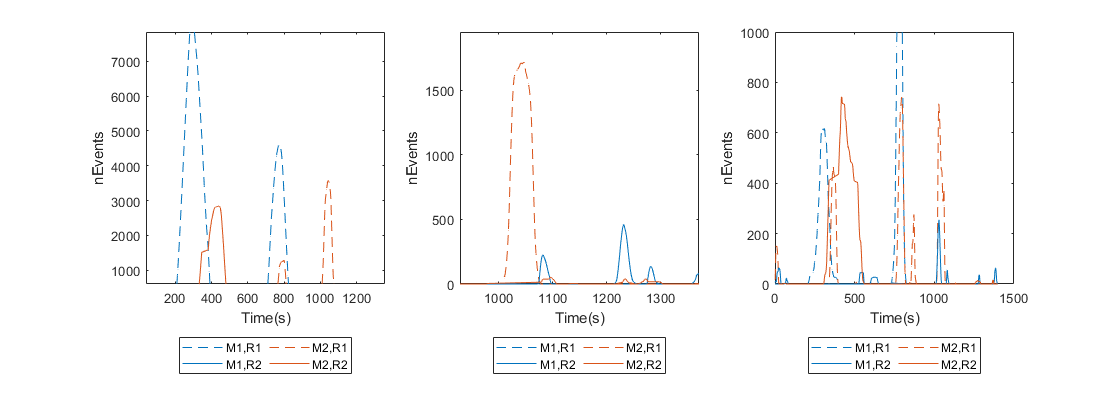

% calculate event number at each time point for second round 
close all
f1=figure(1);f1.Position(3)=2*f1.Position(3);f1.Position(4)=1*f1.Position(4);
for th=1:length(thre)
    time=em{R,th}.time;K=em{R,th}.K;
    for m = 1:2
        s=sum(em{R,th}.timefilter{p,m});
        ne{p,m}=zeros(1,s);
        for r=1:length(time{p,m})
            for e=1:length(time{p,m}{r})
                ne{p,m}(time{p,m}{r}(e):time{p,m}{r}(e)+K{p,m}(r))=ne{p,m}(time{p,m}{r}(e):time{p,m}{r}(e)+K{p,m}(r))+1;
                % for each event add one 
            end
        end
    end
    em{R,th}.ne=ne;
end
% plot first and second round events 
for th=1:length(thre)
    d=[em{1,th}.ne{p,1};em{1,th}.ne{p,2}]; % first round events
    subplot(1,3,th)
    plot(d','--');xlabel('Time(s)');ylabel('nEvents');
    hold on 
    plot(find(em{2,th}.timefilter{p,1}),em{2,th}.ne{p,1},'Color',[0 0.4470 0.7410]);
    plot(find(em{2,th}.timefilter{p,2}),em{2,th}.ne{p,2},'Color',[0.8500 0.3250 0.0980]);
    legend({'M1,R1','M2,R1','M1,R2','M2,R2'},'Location',"southoutside",'Orientation',"horizontal")
    set(legend, 'NumColumns' ,2)
    hold off
    yl=ylim;ylim(yl/2);
end

#### Plot all signals sorted by second round events 

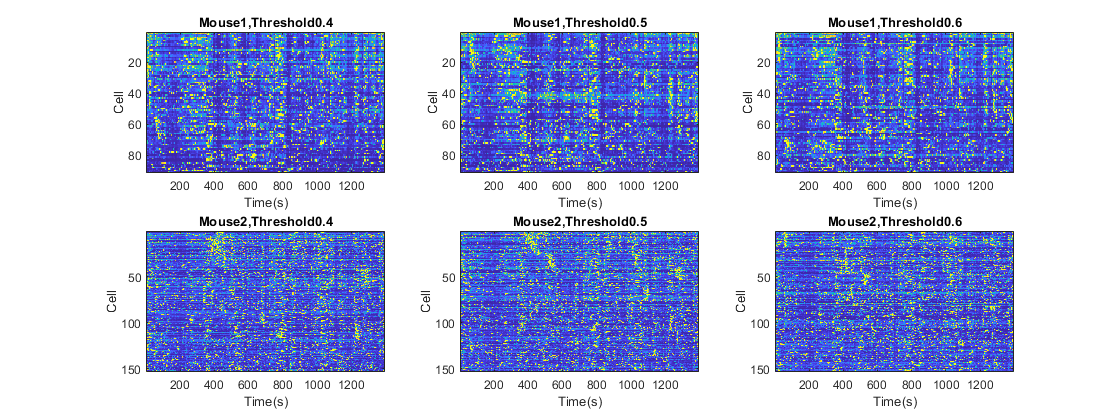

close all
f1=figure(1);f1.Position(3)=2*f1.Position(3);
for th=1:length(thre)
    eve=em{R,th}.eve;cells=em{R,th}.cells;
    c=cell(1,2);
    for m=1:2
        nc=size(eve{p,m},1);c{m}=[1:nc]';
        for i=1:length(cells{p,m})
            c{m}=[cells{p,m}{i}(:);c{m}];
        end
        c{m}=unique(c{m},'stable');c{m}=c{m}(c{m}~=0);
        figure(1)
        subplot(2,3,3*(m-1)+th)
        d=ca_cl{p,m}(c{m},:);
        imagesc(d,'AlphaData',~isnan(d));xlabel('Time(s)');ylabel('Cell');
        title(sprintf('Mouse%d,Threshold%.1f',m,thre(th)));
    end
end